# STEP - 1 / A

#### `generate data in 5 cluster`

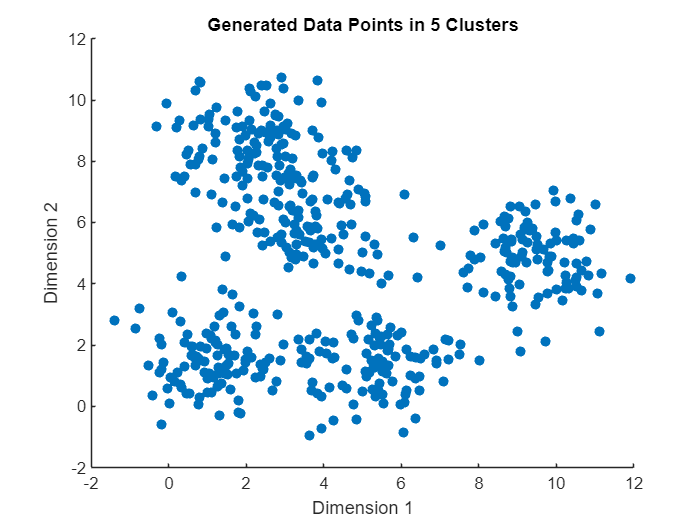

clear,clc,close all
rng(5); % Setting seed for reproducibility

% Generating 500 two-dimensional data points in 5 clusters
numClusters = 5;
numPointsPerCluster = 100;

data = [];
for i = 1:numClusters
    clusterCenter = rand(1, 2) * 10; % Random center for each cluster
    clusterPoints = bsxfun(@plus, randn(numPointsPerCluster, 2), clusterCenter);
    data = [data; clusterPoints];
end
label = repelem([1;2;3;4;5],100,1);

% Plotting the generated data
figure;
scatter(data(:, 1), data(:, 2), 'filled');
title('Generated Data Points in 5 Clusters');
xlabel('Dimension 1');
ylabel('Dimension 2');

- **Use fuzzy c-means toolbox for clustering to see how fcm works**

- **As we can see nearest data are in same cluster and show with different color and center of clusters depicted with a circle shape.**

- **The 'U' output of 'fcm' function represent membership of each data to each cluster**

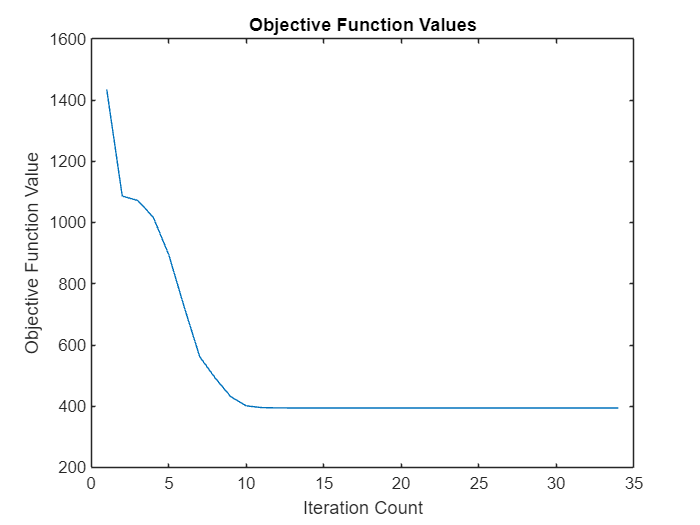

rndidx = randperm(500);
option = fcmOptions(NumClusters=5,MaxNumIteration=1000,Verbose=0,MinImprovement=1e-120);
dataTR = data(rndidx(1:300),:);
labelTR = label(rndidx(1:300));
[center,U,objFcn] = fcm(dataTR,option);
figure
plot(objFcn)
title("Objective Function Values") 
xlabel("Iteration Count")
ylabel("Objective Function Value")

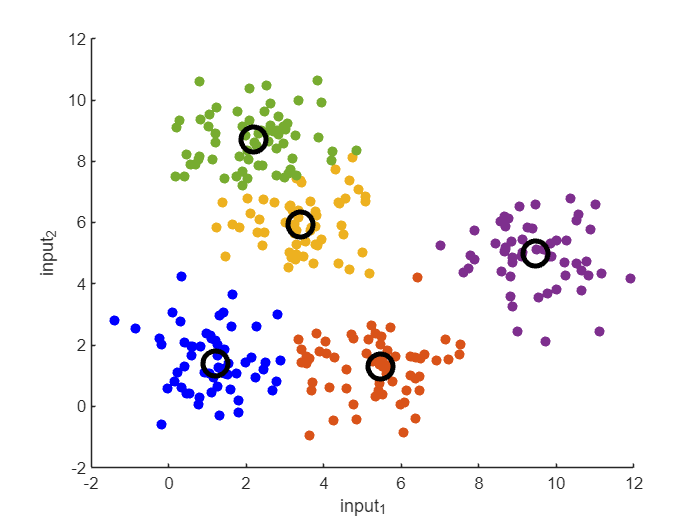

maxU = max(U);
index1 = find(U(1,:) == maxU);
index2 = find(U(2,:) == maxU);
index3 = find(U(3,:) == maxU);
index4 = find(U(4,:) == maxU);
index5 = find(U(5,:) == maxU);
figure
scatter(dataTR(index1,1),dataTR(index1,2),'b',"filled")
hold on
scatter(dataTR(index2,1),dataTR(index2,2),"filled")
scatter(dataTR(index3,1),dataTR(index3,2),"filled")
scatter(dataTR(index4,1),dataTR(index4,2),"filled")
scatter(dataTR(index5,1),dataTR(index5,2),"filled")

plot(center(:,1),center(:,2),"ok",MarkerSize=15,LineWidth=3)
xlabel("input_1")
ylabel("input_2")
hold off

dataTE = data(rndidx(301:end),:);
labelTE = label(rndidx(301:end));

# STEP - 2:5 / B:D

#### `Design mamdani type1, sugino first-order type1, mamdani type2, sugino type2 and ANFIS.`

## Create FIS

I used fuzzy toolbox to create mamdani-type-1 (part b), sugino-type-1 (part c) and mamdani-interval-type-2 (part d)

% Mamdani type 1
mamfis_opts = genfisOptions('FCMClustering','FISType','mamdani','NumClusters',5,'Verbose',0);
mamfis = genfis(dataTR,labelTR,mamfis_opts);
% Sugino type 1
sugfis = convertToSugeno(mamfis);
% Mamdani type 2
mam2fis = convertToType2(mamfis);
% sugino type 2
sug2fis = convertToType2(sugfis);

I fixed the input and output range of FISs to cover test data range also when Output range be [0 5] most of the time predicted values range are less than 5 and grater than 1 and when i round them to reach exact number of cluster(classification), classes 5 and 1 have a lot of error, because data around 4 for example round to 4 from both side, but class 5 has one side and i give it more range [0 6].

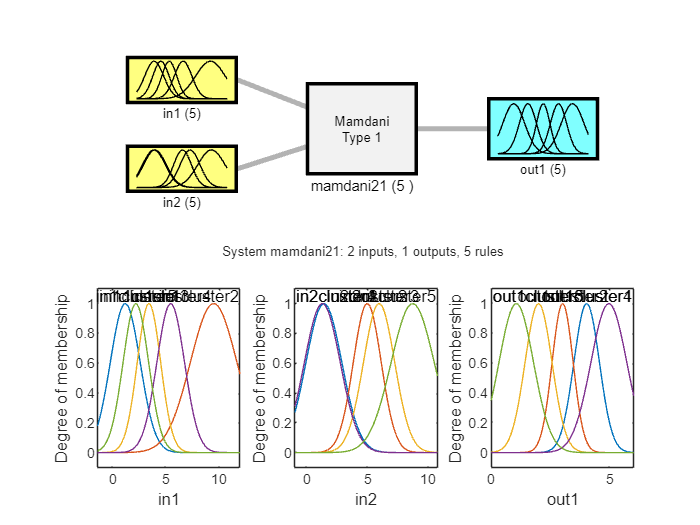

%fix range
mamfis = HelpFunc.fixRange(mamfis,data);
sugfis = HelpFunc.fixRange(sugfis,data);
mam2fis = HelpFunc.fixRange(mam2fis,data);
sug2fis = HelpFunc.fixRange(sug2fis,data);

%% plots

figure
subplot(2,3,[1 2 3]), plotfis(mamfis)
subplot(234), plotmf(mamfis,'input',1)
subplot(235), plotmf(mamfis,'input',2)
subplot(236), plotmf(mamfis,'output',1)

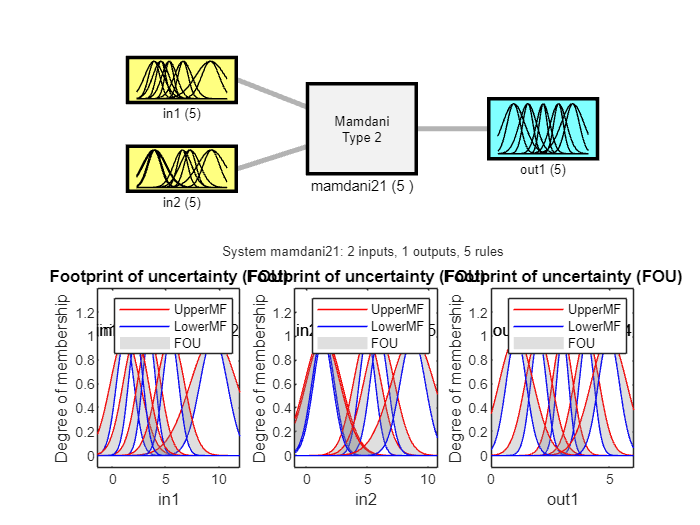

figure
subplot(2,3,[1 2 3]), plotfis(mam2fis)
subplot(234), plotmf(mam2fis,'input',1)
subplot(235), plotmf(mam2fis,'input',2)
subplot(236), plotmf(mam2fis,'output',1)

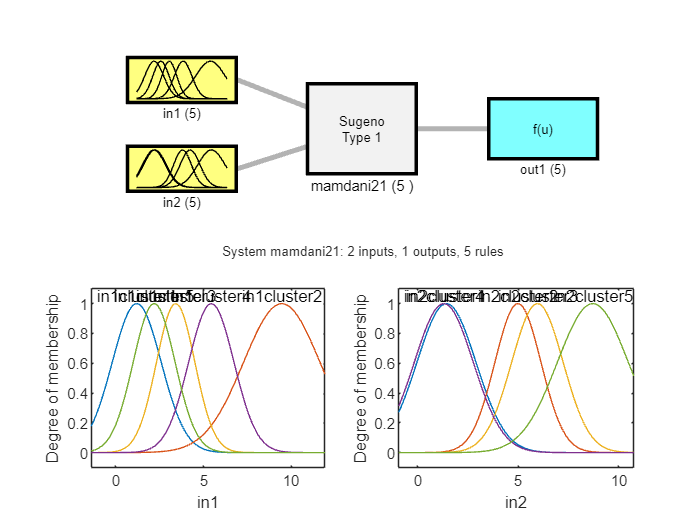

figure
subplot(2,2,[1 2]), plotfis(sugfis)
subplot(223), plotmf(sugfis,'input',1)
subplot(224), plotmf(sugfis,'input',2)

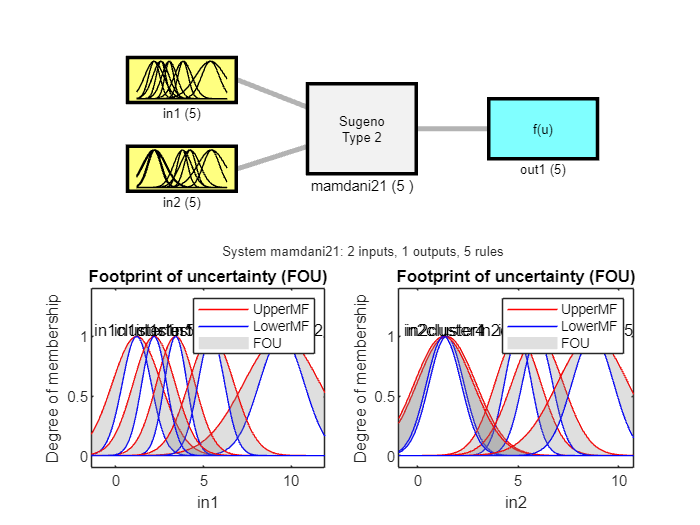

figure
subplot(2,2,[1 2]), plotfis(sug2fis)
subplot(223), plotmf(sug2fis,'input',1)
subplot(224), plotmf(sug2fis,'input',2)

## Tune FIS

Then tune previous FIS for better results

furthermore tune a ANFIS network which used sugino system

% mamdani
[var1,var2] = getTunableSettings(mamfis);
tune_opts = tunefisOptions("Method","ga");
tune_opts.MethodOptions.MaxGenerations = 50;
mamfis_tuned = tunefis(mamfis, [var1;var2], dataTR, labelTR, tune_opts);


Single objective optimization:
30 Variable(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations
    1              400          0.2903           1.426        0
    2              590          0.2903           1.413        1
    3              780          0.2903           1.385        2
    4              970          0.2903           1.336        3
    5             1160          0.2903           1.217        4
    6             1350          0.2814           1.031        0
    7             1540          0.2814          0.8804        1
    8             1730          0.2755          0.7186        0
    9             1920           0.271          0.6137        0
   10             2110          0.2705          0.4894        0
   11     

% type 2
[var1,var2] = getTunableSettings(mam2fis);
tune_opts = tunefisOptions("Method","ga");
tune_opts.MethodOptions.MaxGenerations = 50;
mam2fis_tuned = tunefis(mam2fis, [var1;var2], dataTR, labelTR, tune_opts);


Single objective optimization:
60 Variable(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations
    1              400          0.2757           1.421        0
    2              590          0.2757           1.371        1
    3              780          0.2757           1.293        2
    4              970           0.274             1.2        0
    5             1160          0.2608           1.057        0
    6             1350          0.2608          0.8842        1
    7             1540          0.2459          0.7501        0
    8             1730          0.2459          0.6083        1
    9             1920          0.2452          0.5033        0
   10             2110          0.2447          0.4185        0
   11     


% sugino
[var1,var2] = getTunableSettings(sugfis);
tune_opts = tunefisOptions("Method","ga");
tune_opts.MethodOptions.MaxGenerations = 50;
sugfis_tuned = tunefis(sugfis, [var1;var2], dataTR, labelTR, tune_opts);


Single objective optimization:
25 Variable(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations
    1              400          0.4694           1.599        0
    2              590          0.4694           1.573        1
    3              780          0.4694           1.571        2
    4              970           0.441            1.46        0
    5             1160           0.441           1.342        1
    6             1350          0.3992            1.19        0
    7             1540          0.3899          0.9923        0
    8             1730          0.3425          0.8731        0
    9             1920          0.2843           0.754        0
   10             2110          0.2643          0.6672        0
   11     

% type2
[var1,var2] = getTunableSettings(sug2fis);
tune_opts = tunefisOptions("Method","ga");
tune_opts.MethodOptions.MaxGenerations = 50;
sug2fis_tuned = tunefis(sug2fis, [var1;var2], dataTR, labelTR, tune_opts);


Single objective optimization:
45 Variable(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations
    1              400          0.4819           1.596        0
    2              590          0.4819           1.497        1
    3              780          0.4819           1.465        2
    4              970          0.4471           1.354        0
    5             1160          0.4355           1.223        0
    6             1350          0.4353           1.048        0
    7             1540          0.4204          0.8869        0
    8             1730          0.4159          0.7723        0
    9             1920          0.3738          0.6832        0
   10             2110          0.3283          0.5971        0
   11     

% anfis (neuro-fuzzy)
anfis_tuned = anfis([dataTR,labelTR]);

ANFIS info:
	Number of nodes: 21
	Number of linear parameters: 12
	Number of nonlinear parameters: 12
	Total number of parameters: 24
	Number of training data pairs: 300
	Number of checking data pairs: 0
	Number of fuzzy rules: 4


Start training ANFIS ...

1 	 0.326756
2 	 0.326355
3 	 0.325955
4 	 0.325557
Step size increases to 0.011000 after epoch 5.
5 	 0.32516
6 	 0.324766
7 	 0.324333
8 	 0.323903
Step size increases to 0.012100 after epoch 9.
9 	 0.323474
10 	 0.323048

Designated epoch number reached. ANFIS training completed at epoch 10.

Minimal training RMSE = 0.323048



%fix ranges
mamfis_tuned = HelpFunc.fixRange(mamfis_tuned,data);
sugfis_tuned = HelpFunc.fixRange(sugfis_tuned,data);
mam2fis_tuned = HelpFunc.fixRange(mam2fis_tuned,data);
sug2fis_tuned = HelpFunc.fixRange(sug2fis_tuned,data);


% save 
save mamfis_tuned 
save mam2fis_tuned
save sugfis_tuned
save sug2fis_tuned
save anfis_tuned

# STEP - 5 / E

#### `Design Z-number system`

In this section i use mamfis_tuned membership functions for $\mu_A$

and use a probability distribution (`normpdf`) for $p_x$

then $P_A =\mu_{A\;} p_x$

then $\mu_y^{\prime } =\mu_B \left(P_A \right)$

then $y_{\mathrm{hat}} =\mathrm{defuzz}\left(\mu_y^{\prime } \right)$

note:


$$\mathrm{if}\;X_1 \;\mathrm{is}\;\left(A_1 ,B_1 \right)\;\mathrm{and}\;X_2 \;\mathrm{is}\;\left(A_2 ,B_2 \right)\;\mathrm{then}\;Y\;\mathrm{is}\;\left(A_y ,B_y \right)\Longrightarrow \;\left(A_1 *A_2 \;,B_1 \times B_2 \right)\longrightarrow \;\left(A_y ,B_y \right)\;;\;\;\;*\;\mathrm{refer}\;\mathrm{to}+-\div \times$$


x1bound = -2:0.1:12;
x2bound = -2:0.1:12;
ybound = 0:0.1:6;
[x1,x2,y] = HelpFunc.getpars(mamfis_tuned);
figure
x1.mf{1} = gaussmf(x1bound,x1.par1);
x1.mf{2} = gaussmf(x1bound,x1.par2);
x1.mf{3} = gaussmf(x1bound,x1.par3);
x1.mf{4} = gaussmf(x1bound,x1.par4);
x1.mf{5} = gaussmf(x1bound,x1.par5);
x2.mf{1} = gaussmf(x2bound,x2.par1);
x2.mf{2} = gaussmf(x2bound,x2.par2);
x2.mf{3} = gaussmf(x2bound,x2.par3);
x2.mf{4} = gaussmf(x2bound,x2.par4);
x2.mf{5} = gaussmf(x2bound,x2.par5);
y.mf{1} = @(x) gaussmf(x,y.par1);
y.mf{2} = @(x) gaussmf(x,y.par2);
y.mf{3} = @(x) gaussmf(x,y.par3);
y.mf{4} = @(x) gaussmf(x,y.par4);
y.mf{5} = @(x) gaussmf(x,y.par5);

% probability distribution
% mu = mf center
% sigma = 0.5
x1.p{1} = normpdf(x1bound,x1.par1(2),0.5);
x1.p{2} = normpdf(x1bound,x1.par2(2),0.5);
x1.p{3} = normpdf(x1bound,x1.par3(2),0.5);
x1.p{4} = normpdf(x1bound,x1.par4(2),0.5);
x1.p{5} = normpdf(x1bound,x1.par5(2),0.5);
x2.p{1} = normpdf(x2bound,x2.par1(2),0.5);
x2.p{2} = normpdf(x2bound,x2.par2(2),0.5);
x2.p{3} = normpdf(x2bound,x2.par3(2),0.5);
x2.p{4} = normpdf(x2bound,x2.par4(2),0.5);
x2.p{5} = normpdf(x2bound,x2.par5(2),0.5);
% y.p{1} = normpdf(ybound,y.par1(2),0.5);
% y.p{2} = normpdf(ybound,y.par2(2),0.5);
% y.p{3} = normpdf(ybound,y.par3(2),0.5);
% y.p{4} = normpdf(ybound,y.par4(2),0.5);
% y.p{5} = normpdf(ybound,y.par5(2),0.5);


$$\left(A_1 *A_2 \;,B_1 \times B_2 \right)\equiv \left(x_1 \ldotp \mathrm{mf}\left(:\right)*x_2 \ldotp \mathrm{mf}\left(:\right)\;,x_1 \ldotp p\left(:\right)*x_2 \ldotp p\left(:\right)\right)$$


for i = 1:5
    input.mf_A{i} = x1.mf{i} .* x2.mf{i};
    input.p_x{i} = x1.p{i} .* x2.p{i};
end


$$P_A =\mu_{A\;} p_x$$


for i = 1:5
    input.P_A{i} = input.mf_A{i} .* input.p_x{i};
end


$$\mu_y^{\prime } =\mu_B \left(P_A \right)$$


for i = 1:5
    mf_hat{i} = y.mf{i}(input.P_A{i});
end


$$y_{\mathrm{hat}} =\mathrm{defuzz}\left(\mu_y^{\prime } \right)$$


for i = 1:5
    pred_Z(i) = defuzz(x1bound,mf_hat{i},'centroid');
end

# STEP - 6 / F

#### `Compare the results`

## Eval FIS

Evaluate results with test data

pred_mam = evalfis(mamfis_tuned, dataTE);
pred_mam2 = evalfis(mam2fis_tuned, dataTE);
pred_sug = evalfis(sugfis_tuned, dataTE);
pred_sug2 = evalfis(sug2fis_tuned, dataTE);
pred_anfis = evalfis(anfis_tuned, dataTE);

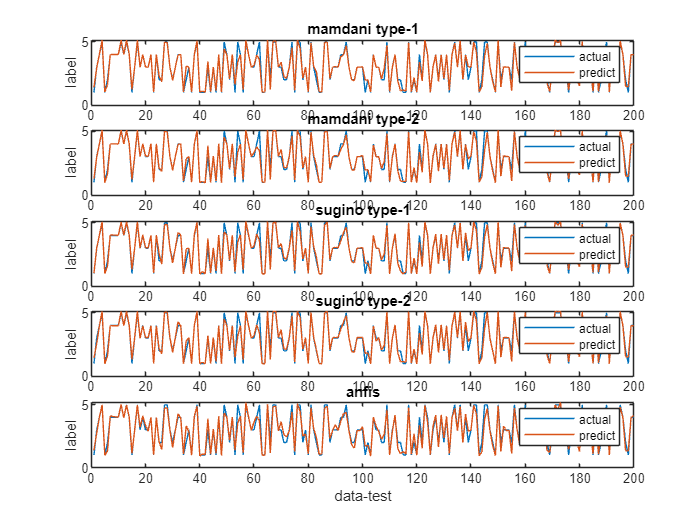

figure;
subplot(5,3,[1 2 3])
plot(1:200,labelTE,1:200,pred_mam)
title("mamdani type-1"),ylabel("label"),legend(["actual","predict"])
subplot(5,3,[4 5 6])
plot(1:200,labelTE,1:200,pred_mam2)
title("mamdani type-2"),ylabel("label"),legend(["actual","predict"])
subplot(5,3,[7 8 9])
plot(1:200,labelTE,1:200,pred_sug)
title("sugino type-1"),ylabel("label"),legend(["actual","predict"])
subplot(5,3,[10 11 12])
plot(1:200,labelTE,1:200,pred_sug2)
title("sugino type-2"),ylabel("label"),legend(["actual","predict"])
subplot(5,3,[13 14 15])
plot(1:200,labelTE,1:200,pred_anfis)
title("anfis"),xlabel("data-test"),ylabel("label"),legend(["actual","predict"])

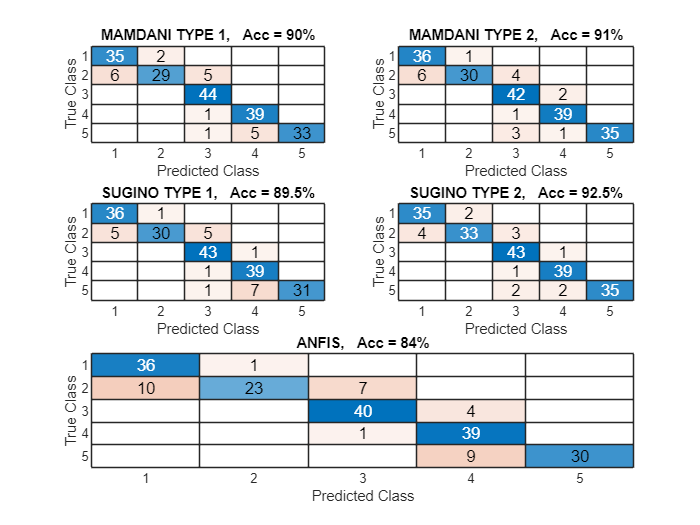

figure
subplot(3,2,1) % mam1
confusionchart(labelTE,round(pred_mam))
cm = confusionmat(labelTE,round(pred_mam));
acc = sum(diag(cm)) / sum(cm(:));
title("MAMDANI TYPE 1,   Acc = "+ acc*100 + "%")
subplot(3,2,2) % mam2
confusionchart(labelTE,round(pred_mam2))
cm = confusionmat(labelTE,round(pred_mam2));
acc = sum(diag(cm)) / sum(cm(:));
title("MAMDANI TYPE 2,   Acc = "+ acc*100 + "%")
subplot(3,2,3) % sug1
confusionchart(labelTE,round(pred_sug))
cm = confusionmat(labelTE,round(pred_sug));
acc = sum(diag(cm)) / sum(cm(:));
title("SUGINO TYPE 1,   Acc = "+ acc*100 + "%")
subplot(3,2,4) % sug2
confusionchart(labelTE,round(pred_sug2))
cm = confusionmat(labelTE,round(pred_sug2));
acc = sum(diag(cm)) / sum(cm(:));
title("SUGINO TYPE 2,   Acc = "+ acc*100 + "%")
subplot(3,2,[5 6]) % anfis
confusionchart(labelTE,round(pred_anfis))
cm = confusionmat(labelTE,round(pred_anfis));
acc = sum(diag(cm)) / sum(cm(:));
title("ANFIS,   Acc = "+ acc*100 + "%")

# STEP - 7 / G

#### `Suggestion to increase interpretability in fuzzy clustering`